clear;clc;close all;

R = 10;
L = 0.01;
C = 1e-6;

s = tf('s');
G_tf = 1/(L*C*s^2 + R*C*s + 1);

% 转换为 zpk 模型
G_zpk = zpk(G_tf);
[z, p, k] = zpkdata(G_zpk, 'v')


z =

  空的 0×1 double 列向量



p = 1.0e+03 *

  -0.5000 + 9.9875i
  -0.5000 - 9.9875i


k = 100000000

% 转换为 ss 模型
G_ss = ss(G_tf);

% 打印出三种模型看看它们的样子
% 细节点：没有设置频率，是这个函数自带的自动调节
disp('---传递函数(tf)---');G_tf

---传递函数(tf)---

G_tf =
 
             1
  -----------------------
  1e-08 s^2 + 1e-05 s + 1
 
连续时间传递函数。
模型属性


disp('---零极点增益(zpk)---');G_zpk

---零极点增益(zpk)---

G_zpk =
 
         1e+08
  --------------------
  (s^2 + 1000s + 1e08)
 
连续时间零点/极点/增益模型。
模型属性


disp('---状态空间(ss)---');G_ss

---状态空间(ss)---

G_ss =
 
  A = 
               x1          x2
   x1       -1000  -1.221e+04
   x2        8192           0
 
  B = 
        u1
   x1  128
   x2    0
 
  C = 
          x1     x2
   y1      0  95.37
 
  D = 
       u1
   y1   0
 
连续时间状态空间模型。


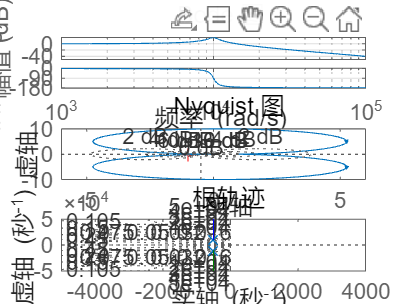

figure;
% 如果想手动设置范围，可以：w = logspace(2, 5, 1000);figure;bode(G_tf, w); grid on; title('手动指定频率范围的 Bode 图')
subplot(3,1,1); bode(G_tf); grid on; title('Bode 图');
subplot(3,1,2); nyquist(G_tf); grid on; title('Nyquist 图');
subplot(3,1,3); rlocus(G_tf); grid on; title('根轨迹');